# Demo 11

% demo to get easy data from a VLP simulation using a sensor with
% photodiodes and light emitters

% n_Emitters -> number of light emitters
% x_Emitters -> number of light emitters per X
% y_Emitters -> number of light emitters per Y

## Prepare the Workspace

clear all;
close all;

addpath('../projgeom/')

## Room Variables

room_width = 5;                 % Room Width (in meters)
room_length = 3.6;              % Room Length (in meters)
room_height = 2.7;              % Room Height (in meters)

%Building the room
Em_Base_HTM = Trans3(room_width/2,room_length/2,room_height)*RotX3(pi);

## Light Emitters Variables


x_Emitters = 4;                 % Numbers of Emitters on X 
y_Emitters = 4;                 % Numbers of Emitters on Y

n_Emitters = x_Emitters * y_Emitters;   % Number of emitters

Emitters_between_row = 1.3;     % Distance between light emitters on X  
Emitters_between_columns = 0.9; % Distance between light emitters on Y

start_x = 0.55;                 % Position of the first Led on X
start_y = 0.35;                 % Position of the first Led on Y

Pb = 1;                        % Transmitted power
Ps = 1;                         % Signal component of the transmitted power
m = 4;                          % Lambertian mode number


## Sensor Variables

Np = 10;                         % Number of parallels in the sensor
Nm = 3;                         % Number of meridians in the sensor

sensor_radius = 0.25;

n_Receivers = Np*Nm;        % Number of receivers
Ar = 1e-6;                  % Active receiving area
Ts = 1;                   % Optical filter gain
n = 1;                      % Receiver's internal refractive index
Psi = pi/4;                 % Hemi-Fov
R = 1;                      % Receiver's responsivity


## Grid and Measuremnt Variables

% Measurement Points
n_Positions = 100;              % Number of Measurement Positions

x_Positions = 10;
y_Positions = 10;

rotations_per_position = 16;     % Rotations per Measurement Positions
n_read = 1800;                    % Number of Measurements per Rotation 


% add the path to the projective geometry function
addpath('../projgeom/')


## Create and plot the light emitters    

Emitters = newEmitters(n_Emitters, Pb, Ps, m);

row_light = 1;
column_light = 1;

start_at_x = (room_width/2) + Emitters_between_row - (start_x*2) - 0.1

start_at_x = 2.6000

start_at_y = (room_height/2) + Emitters_between_columns - (start_y) -0.1

start_at_y = 1.8000

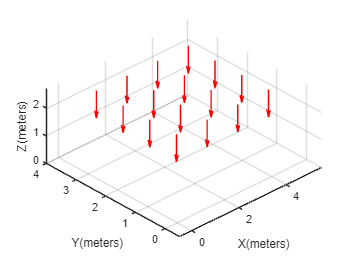


for i = 1:n_Emitters
    Emitters(i).HTM = Em_Base_HTM * Trans3(-(start_at_x) - (Emitters_between_row / 2) + (Emitters_between_row * row_light) ,start_at_y + (Emitters_between_columns/2) - Emitters_between_columns * column_light,0) * RotZ3(pi/2);
    row_light = row_light + 1;
    if row_light > x_Emitters
        row_light = 1;
        column_light = column_light + 1;
    end
end

figure()
PlotHTMArray(Emitters);
axis([-0.5 5.5 -0.5 4 0 2.7]);
view(3);
ylabel('Y(meters)')
xlabel('X(meters)')
zlabel('Z(meters)')
grid on
view([-43.35 53.33]);

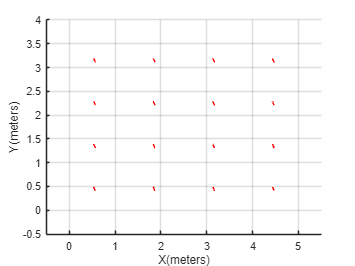


figure()
PlotHTMArray(Emitters);
axis([-0.5 5.5 -0.5 4 0 2.7]);
view(3);
ylabel('Y(meters)')
xlabel('X(meters)')
grid on
view([0 90.00])

## Create and plot the receiver

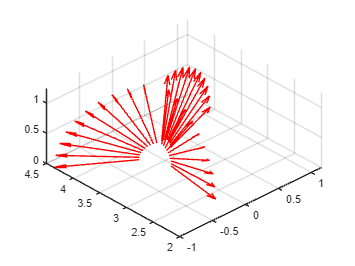

% Create the receiver structure:
Receivers = newReceivers(n_Receivers,Ar, Ts, n, Psi, R);
% Receivers are organized in Parallel and Meridians arragement of photo
% detectors, with Nm Meridians and Np Parallels, in a sphere with
% radius=0.25
PDSensor = vlpCreateSensorParMer(Receivers, Np, Nm, 0.25,pi/8);

% The sensor is initially placed at point (X,Y) = (0,3.6,0)
PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3.6,0));

figure(40)
PlotHTMArray(PDSensor);
view(3);
grid on;
view([-43.35 53.33]);

## Set the Variables for the receiver circuit

Bw = 10e4;              % Bandwidth for the receiver circuit
Theta = 273+30;         % Thermodynamic temperature of feedback resistor (in Kelvin) at 30degrees Celsius

nRec_v = ones(n_Receivers, 1);   % Vector of ones for the receivers

Z = 1e6 * nRec_v;       % Feedback resistors - Vector with transimpedance feedback resistors
Z_p = 100e6 * nRec_v;   % PD equivalent impedance - Vector with the photo-siode equivalent impedances


## Set the variables for the noise

s_i = 1.3e-15*nRec_v;    % Current noise "plateau" at 1.3 fA/sqrt(Hz) - Vector with the operational amplifiers current PSD
s_v = 4.8e-9*nRec_v;     % Voltage noise "plateau" at 4.8 nV/sqrt(Hz) - Vector with the operational amplifiers voltage PSD


## Compute and Plot received indication


x_distance = room_width / (x_Positions - 1);
y_distance = room_length / (y_Positions - 1);

rotator = 2*pi/(rotations_per_position);
rotator_deg = 360/(rotations_per_position);

mySensorArray = zeros(1, n_Emitters * n_Receivers);
myLocationArray = zeros (1, 3);

% To show the sensor going from one position to another just uncomment the lines bellow
% figure(20)
% PlotHTMArray(Emitters);
% hx = PlotHTMArrayPr(PDSensor);
% axis([-0.5 5.5 -0.5 4 0 2.7]);
% view(3);
% grid on
% view([-43.35 53.33]);
experiment = 0;

Current_X = 0.0;
Current_Y = room_length;
Current_Theta = -pi;

position_number = 0;
% Change the path of the .csv files if necessary
SensorFile = fopen('../../mySensorData.csv', 'w');
LocationFile = fopen('../../myLocationData.csv', 'w');
fclose(SensorFile);
fclose(LocationFile);

SensorFile = fopen('../../mySensorData.csv', 'a');
LocationFile = fopen('../../myLocationData.csv', 'a');
count_for_percentage = 0;
total_points_for_percentage = n_Positions * rotations_per_position * n_read;
% fprintf('total_points_for_percentage: %d\n', total_points_for_percentage)

for l = 1: y_Positions
    if (~(l == 1))
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-y_distance,0));
        Current_Y = Current_Y - y_distance;
    end
    for m=1:x_Positions
        if (m == 1)

        elseif (mod(l,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(x_distance,0,0));
            Current_X = Current_X + x_distance;
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-x_distance,0,0));
            Current_X = Current_X - x_distance;
        end
        for n = 1: rotations_per_position
                Current_Theta = Current_Theta + rotator;
                if (n == 1)
                    Current_Theta = -pi;
                end
                PDSensor=vlpMoveSensor(PDSensor, Trans3(-Current_X,-Current_Y,0));
                PDSensor=vlpMoveSensor(PDSensor, Trans3(0,0,0)*RotZ3(rotator));
                PDSensor=vlpMoveSensor(PDSensor, Trans3(Current_X,Current_Y,0));

            [ Y nu ] = vlpRecIndication( Emitters, PDSensor, Bw, Z, s_i, s_v, Z_p, Theta );


            for i2 = 1:n_read
                position_number = position_number +1;

                Nu = repmat(nu,1,n_Emitters);
                s = sqrt(Nu).*randn(size(Y));
                Ystar = Y + s;

                for k = 1:n_Emitters
                    new_Y = Ystar(:, k);
                    new_Y = new_Y';
                    for j = 1: n_Receivers
                        mySensorArray(1, k*n_Receivers - (n_Receivers - j)) = sqrt(sum((new_Y(j).*new_Y(j)),2));
                        myLocationArray(1, 1) = Current_X;
                        myLocationArray(1, 2) = Current_Y;
                        myLocationArray(1, 3) = Current_Theta;
                    end
                end
                % We are writing each rotation read directly to the file,
                % to free up memory
                fprintf(SensorFile, '%f,', mySensorArray(1, 1:end-1));
                fprintf(SensorFile, '%f\n', mySensorArray(1, end));
                fprintf(LocationFile, '%f,%f,%f\n', myLocationArray(1,1), myLocationArray(1,2), myLocationArray(1,3));
                Pr_v = sqrt(sum((Ystar.*Ystar),2));
                for k = 1:n_Receivers
                   PDSensor(k).Pr = Pr_v(k);
                end
                  count_for_percentage = count_for_percentage + 1;
%                         fprintf('total_points_for_percentage: %d\n', count_for_percetange)
                  percetange_for_show = (count_for_percentage / total_points_for_percentage) * 100;
%                 pause(0.000001)
%                 figure(20)
%                 delete(hx)
%                 Plot the receiver power intensities, scaled
%                 To present a graph with the sensor going from position to position uncomment the line bellow
%                 hx = PlotHTMArrayPr(PDSensor);
            end
        % Write the percentage to the command window on the same line using '\r'
        fprintf('Percentage: %.5f%%\r', percetange_for_show); 
        end

    end
end

Percentage: 0.06250%
Percentage: 0.12500%
Percentage: 0.18750%
Percentage: 0.25000%
Percentage: 0.31250%
Percentage: 0.37500%
Percentage: 0.43750%
Percentage: 0.50000%
Percentage: 0.56250%
Percentage: 0.62500%
Percentage: 0.68750%
Percentage: 0.75000%
Percentage: 0.81250%
Percentage: 0.87500%
Percentage: 0.93750%
Percentage: 1.00000%
Percentage: 1.06250%
Percentage: 1.12500%
Percentage: 1.18750%
Percentage: 1.25000%
Percentage: 1.31250%
Percentage: 1.37500%
Percentage: 1.43750%
Percentage: 1.50000%
Percentage: 1.56250%
Percentage: 1.62500%
Percentage: 1.68750%
Percentage: 1.75000%
Percentage: 1.81250%
Percentage: 1.87500%
Percentage: 1.93750%
Percentage: 2.00000%
Percentage: 2.06250%
Percentage: 2.12500%
Percentage: 2.18750%
Percentage: 2.25000%
Percentage: 2.31250%
Percentage: 2.37500%
Percentage: 2.43750%
Percentage: 2.50000%
Percentage: 2.56250%
Percentage: 2.62500%
Percentage: 2.68750%
Percentage: 2.75000%
Percentage: 2.81250%
Percentage: 2.87500%
Percentage: 2.93750%
Percentage: 3

fclose(SensorFile);
fclose(LocationFile);

% myArray


## Write the matrix in a .csv file

% writematrix(mySensorArray, '../../mySensorData.csv');
% writematrix(myLocationArray, '../../myLocationData.csv');